clear
close all
clc

% Load OCP data from Excel files
file1 = 'Area vs Ecorr pitting.xlsx';
file2 = 'Area vs Ecorr not pitting.xlsx';

% Read OCP data from both Excel files
data_pitting = xlsread(file1, 1);  % Assuming data is in the first sheet
data_nonpitting = xlsread(file2, 1);  % Assuming data is in the first sheet

% Separate distance and OCP values for deformed and non-deformed datasets
Area_Pitting = data_pitting(:, 1);
Ecorr_Pitting = data_pitting(:, 2);

Area_nonPitting = data_nonpitting(:, 1);
Ecorr_nonPitting = data_nonpitting(:, 2);


% Tabulate data
Area = [Area_nonPitting; Area_Pitting];
Pitting = [[repmat("No Pitting", 158,1)]; [repmat("Pitting", 39,1)] ];
Ecorr = [Ecorr_nonPitting; Ecorr_Pitting];
data = table( Area, Pitting, Ecorr);

% Fit a linear model to determine if OCP is different between landings
% where pits occured and if this is affected by area.
fit_pit = fitlm(data, 'interactions', 'RobustOpts','on')

fit_pit = Linear regression model (robust fit):
    Ecorr ~ 1 + Area*Pitting

Estimated Coefficients:
                            Estimate        SE         tStat       pValue  
                            _________    _________    _______    __________

    (Intercept)              -0.47061     0.013838    -34.008    1.9234e-83
    Area                    -0.011178    0.0040302    -2.7736     0.0060889
    Pitting_Pitting          0.041683     0.039951     1.0434       0.29808
    Area:Pitting_Pitting    -0.021278     0.017716    -1.2011        0.2312


Number of observations: 197, Error degrees of freedom: 193
Root Mean Squared Error: 0.0714
R-squared: 0.0576,  Adjusted R-Squared: 0.0429
F-statistic vs. constant model: 3.93, p-value = 0.00941

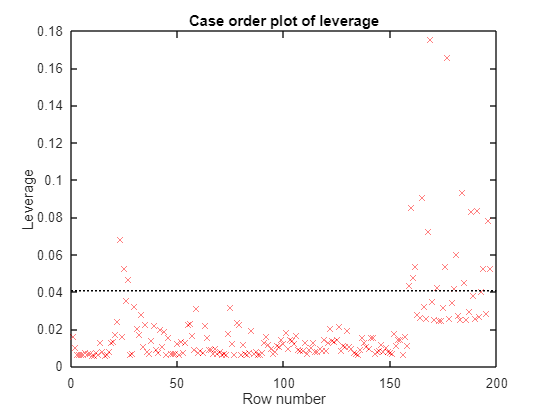

plotDiagnostics(fit_pit)

anova(fit_pit)

ans = 4×5 table
                      SumSq       DF       MeanSq        F        pValue  
                    __________    ___    __________    ______    _________

    Area              0.049945      1      0.049945    9.7894    0.0020273
    Pitting         0.00034744      1    0.00034744    0.0681       0.7944
    Area:Pitting     0.0073597      1     0.0073597    1.4426       0.2312
    Error              0.98466    193     0.0051019                       


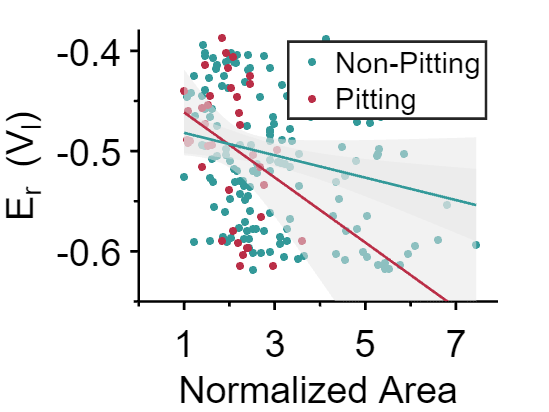

% Plot the raw data (Area vs Pitting, scatter)
figure;
hold on;
scatter(Area_nonPitting, Ecorr_nonPitting, 'o', 'MarkerEdgeColor', 'none', 'MarkerFaceColor', [0.2, 0.6, 0.6]); % blue for non-deformed
scatter(Area_Pitting, Ecorr_Pitting, 'o', 'MarkerEdgeColor', 'none', 'MarkerFaceColor', [0.73, 0.18, 0.28]); % pink for deformed


% Set the axis limits and ticks based on the data range
xlim([0 7.9])  % Adjust x-axis limits
xticks(1:2:8)

ylim([-0.65 -0.38])
%yticks(-0.8:0.1:-0.1)

h = gca; % Get axis to modify
h.XAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.XAxis.MinorTickValues = 0:2:8; % Minor ticks which don't line up with majors

h.YAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.YAxis.MinorTickValues = -0.85:0.05:-0.1; % Minor ticks which don't line up with majors 

% Format the plot appearance
set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'XColor', 'k', 'YColor', 'k', 'LineWidth', 1, ...
    'FontSize', 28, 'linewidth', 2, 'FontWeight', 'normal');

% Label axes
xlabel('Normalized Area', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28, 'Color', 'black')
ylabel('E_c_o_r_r (V_A_g_/_A_g_C_l)', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28, 'Color', 'black')

newcolors={'[0.73, 0.18, 0.28]', '[0.2, 0.6, 0.6]'};

colororder(newcolors)
%axis equal;  % Makes the x-axis and y-axis have the same length
%legend('Pitting','Non-Pitting','FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 22);


% Generate points for plotting the regression curves
Area = transpose( linspace(min(Area), max(Area), 100) ); % Range of Area
Pitting = repmat("Pitting", 100, 1);
pred_Pit = table(Area, Pitting);

Pitting = repmat("No Pitting", 100, 1);
pred_NoPit = table(Area, Pitting);

[y_fit_pit, y_ci_pit] = predict(fit_pit, pred_Pit); % Predicted values with 95% confidence intervals
[y_fit_no, y_ci_no] = predict(fit_pit, pred_NoPit); % Predicted values with 95% confidence intervals

% Fill the confidence region (shaded area) FIRST
fill([Area; flipud(Area)], [y_ci_pit(:,2); flipud(y_ci_pit(:,1))], [0.9 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.5);
fill([Area; flipud(Area)], [y_ci_no(:,2); flipud(y_ci_no(:,1))], [0.9 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.5);

% Plot the regression lines SECOND
prob_line = plot(Area, y_fit_pit, 'LineWidth', 2, 'Color', '[0.73, 0.18, 0.28]'); % Red dashed line for the probability curve
prob_line = plot(Area, y_fit_no, 'LineWidth', 2, 'Color', '[0.2, 0.6, 0.6]'); % Red dashed line for the probability curve

% Add a legend for the probability line
%legend(prob_line, 'Poisson Regression', 'FontSize', 20, 'Location', 'northeast');

legend('Non-Pitting','Pitting', '', '', '', '', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 22);


hold off